clc 
clear
close all

# **Safety Filter Design**

# SWITCHING ,  HJ REACHABILITY, CONTROL BARRIER FUNCTION and  PREDICTIVE

# 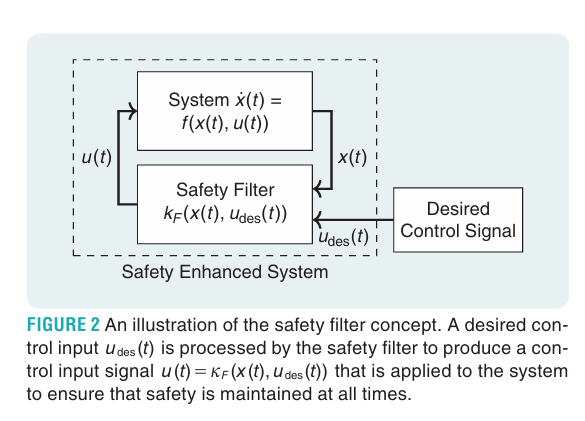 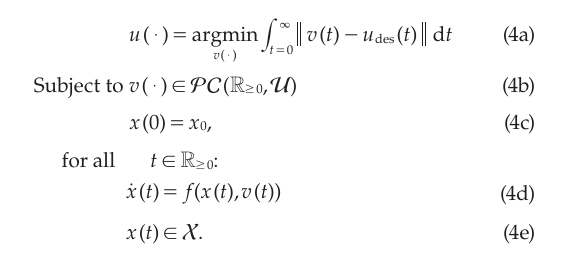

# System Dynamic Inverted Pendulum

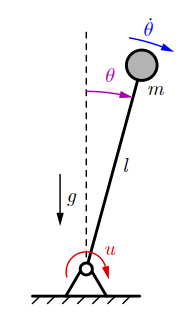

## Inverted Pendulum dynamic equation: 

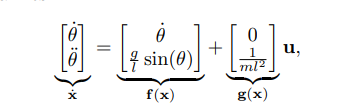

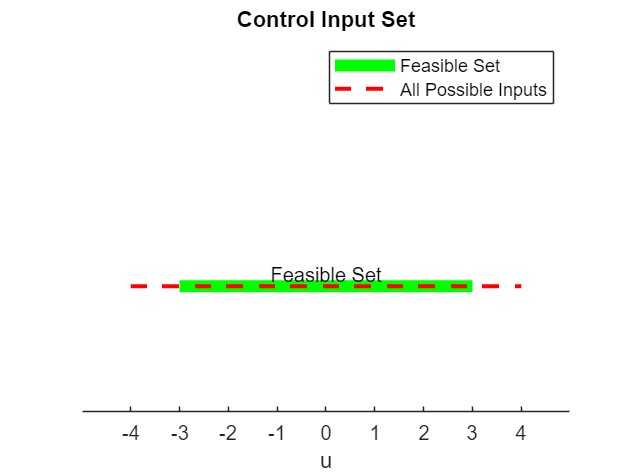

g = 9.81; % acceleration due to gravity (m/s^2)
l = 1.0;  % length of the pendulum (m)
m = 1.0;  % mass of the pendulum (kg)
% syms  theta theta_dot
% x = [theta theta_dot]
% Parameters for visualization
u_max = 3;       % Maximum control input
u_range = 4;     % Range for all possible inputs

% Create figure for control input set U
figure;
hold on;
title('Control Input Set');
xlabel('u');

% Plot feasible control input set as a line
line([-u_max, u_max], [0, 0], 'Color', 'g', 'LineWidth', 6, 'DisplayName', 'Feasible Set');
text(0, 0, 'Feasible Set', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');

% Plot larger range for all possible inputs as a dashed line
line([-u_range, u_range], [0, 0], 'Color', 'r', 'LineStyle', '--', 'LineWidth', 2, 'DisplayName', 'All Possible Inputs');

% Adjust the plot limits and aesthetics
xlim([-u_range-1, u_range+1]);
xticks([-4 -3 -2 -1 0 1 2 3 4])
ylim([-1, 2]);
set(gca, 'YTick', []); % Remove y-axis ticks
set(gca, 'YColor', 'none'); % Remove y-axis line
legend('show');
hold off;

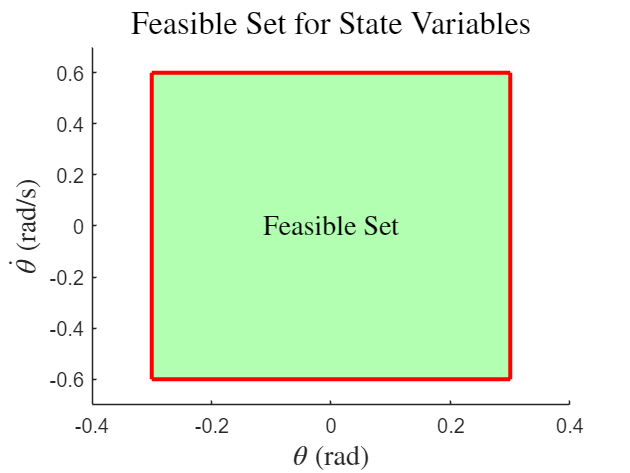

drawnow;
% Visualization of the feasible set
theta_max = 0.3;       % Maximum angle (rad)
theta_dot_max = 0.6;   % Maximum angular velocity (rad/s)

% Create figure for feasible set visualization
figure;
hold on;
title('Feasible Set for State Variables', 'Interpreter', 'latex', 'FontSize', 16);
xlabel('$\theta$ (rad)', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\dot{\theta}$ (rad/s)', 'Interpreter', 'latex', 'FontSize', 14);

% Plot feasible region
x1 = [-theta_max, theta_max, theta_max, -theta_max, -theta_max];
x2 = [-theta_dot_max, -theta_dot_max, theta_dot_max, theta_dot_max, -theta_dot_max];
fill(x1, x2, 'g', 'FaceAlpha', 0.3);

% Plot boundaries
line([-theta_max, -theta_max], [-theta_dot_max, theta_dot_max], 'Color', 'r', 'LineWidth', 2);
line([theta_max, theta_max], [-theta_dot_max, theta_dot_max], 'Color', 'r', 'LineWidth', 2);
line([-theta_max, theta_max], [-theta_dot_max, -theta_dot_max], 'Color', 'r', 'LineWidth', 2);
line([-theta_max, theta_max], [theta_dot_max, theta_dot_max], 'Color', 'r', 'LineWidth', 2);

text(0, 0, 'Feasible Set', 'HorizontalAlignment', 'center', 'Interpreter', 'latex', 'FontSize', 14);

% Set plot limits
xlim([-0.4, 0.4]);
ylim([-0.7, 0.7]);
hold off; drawnow;

## Desired Controller (Policy)

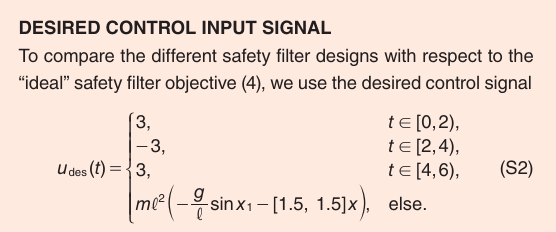

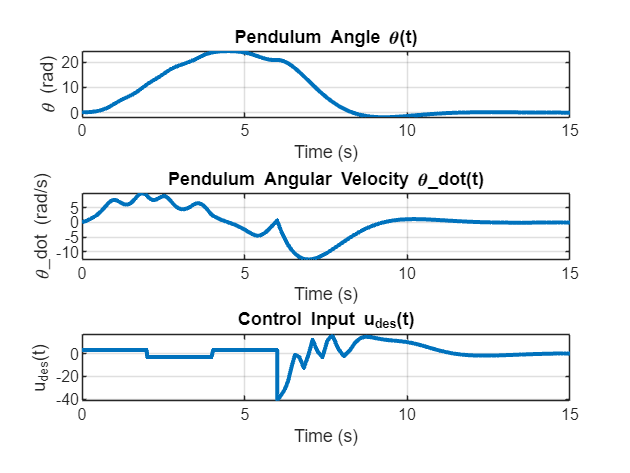

% Initial conditions
theta0 = 0.1; % initial angle (rad)
theta_dot0 = 0; % initial angular velocity (rad/s)
x0 = [theta0; theta_dot0];

% Time span
tspan = [0 15];

% Solve the differential equation
[t, x] = ode45(@(t, x) pendulum_dynamics(t, x, g, l, m, @(t, x) control_input(t, x, g, l, m)), tspan, x0);

% Plot the results
figure;
subplot(3, 1, 1);
plot(t, x(:, 1), 'LineWidth', 2);
title('Pendulum Angle \theta(t)');
xlabel('Time (s)');
ylabel('\theta (rad)');
grid on;

subplot(3, 1, 2);
plot(t, x(:, 2), 'LineWidth', 2);
title('Pendulum Angular Velocity \theta\_dot(t)');
xlabel('Time (s)');
ylabel('\theta\_dot (rad/s)');
grid on;

% Calculate and plot the control input over time
u_vals = arrayfun(@(ti) control_input(ti, x(find(t==ti),:)', g, l, m), t);
subplot(3, 1, 3);
plot(t, u_vals, 'LineWidth', 2);
title('Control Input u_{des}(t)');
xlabel('Time (s)');
ylabel('u_{des}(t)');
grid on; drawnow;

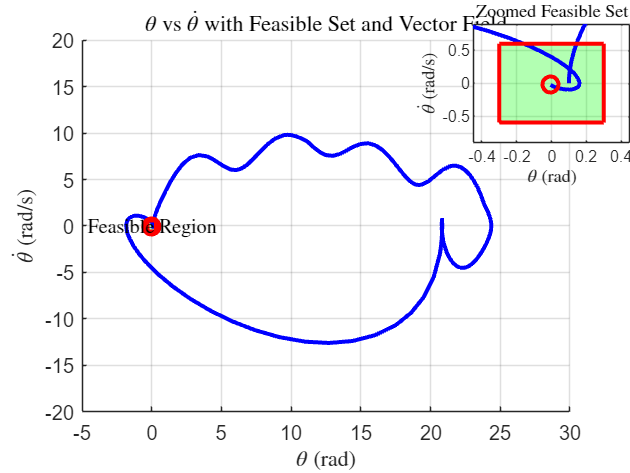

% Parameters
theta_max = 0.3;  % Maximum angle (rad)
theta_dot_max = 0.6; % Maximum angular velocity (rad/s)

% Create the main figure
figure;
hold on;
title('$\theta$ vs $\dot{\theta}$ with Feasible Set and Vector Field', 'Interpreter', 'latex');
xlabel('$\theta$ (rad)', 'Interpreter', 'latex');
ylabel('$\dot{\theta}$ (rad/s)', 'Interpreter', 'latex');

% Plot feasible region
x1 = [-theta_max, theta_max, theta_max, -theta_max, -theta_max];
x2 = [-theta_dot_max, -theta_dot_max, theta_dot_max, theta_dot_max, -theta_dot_max];
fill(x1, x2, 'g', 'FaceAlpha', 0.3);

% Plot trajectories
plot(x(:, 1), x(:, 2), 'b', 'LineWidth', 2);

% Add the endpoint of the trajectory
plot(x(end, 1), x(end, 2), 'ro', 'MarkerSize', 8, 'LineWidth', 2);

% Plot boundaries
line([-theta_max, -theta_max], [-theta_dot_max, theta_dot_max], 'Color', 'r', 'LineWidth', 2);
line([theta_max, theta_max], [-theta_dot_max, theta_dot_max], 'Color', 'r', 'LineWidth', 2);
line([-theta_max, theta_max], [-theta_dot_max, -theta_dot_max], 'Color', 'r', 'LineWidth', 2);
line([-theta_max, theta_max], [theta_dot_max, theta_dot_max], 'Color', 'r', 'LineWidth', 2);

text(0, 0, 'Feasible Region', 'HorizontalAlignment', 'center', 'Interpreter', 'latex');

% Set plot limits
xlim([-5, 30]);
ylim([-20, 20]);
grid on;

% Create inset plot
axes('Position', [0.75 .7 .25 .25]);
box on;
hold on;
title('Zoomed Feasible Set', 'Interpreter', 'latex');
xlabel('$\theta$ (rad)', 'Interpreter', 'latex');
ylabel('$\dot{\theta}$ (rad/s)', 'Interpreter', 'latex');
fill(x1, x2, 'g', 'FaceAlpha', 0.3);
plot(x(:, 1), x(:, 2), 'b', 'LineWidth', 2);
plot(x(end, 1), x(end, 2), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
line([-theta_max, -theta_max], [-theta_dot_max, theta_dot_max], 'Color', 'r', 'LineWidth', 2);
line([theta_max, theta_max], [-theta_dot_max, theta_dot_max], 'Color', 'r', 'LineWidth', 2);
line([-theta_max, theta_max], [-theta_dot_max, -theta_dot_max], 'Color', 'r', 'LineWidth', 2);
line([-theta_max, theta_max], [theta_dot_max, theta_dot_max], 'Color', 'r', 'LineWidth', 2);
xlim([-theta_max*1.5, theta_max*1.5]);
ylim([-theta_dot_max*1.5, theta_dot_max*1.5]);
grid on;
hold off; drawnow;

####  SWITCHING SAFETY FILTER  

#### LQR controller

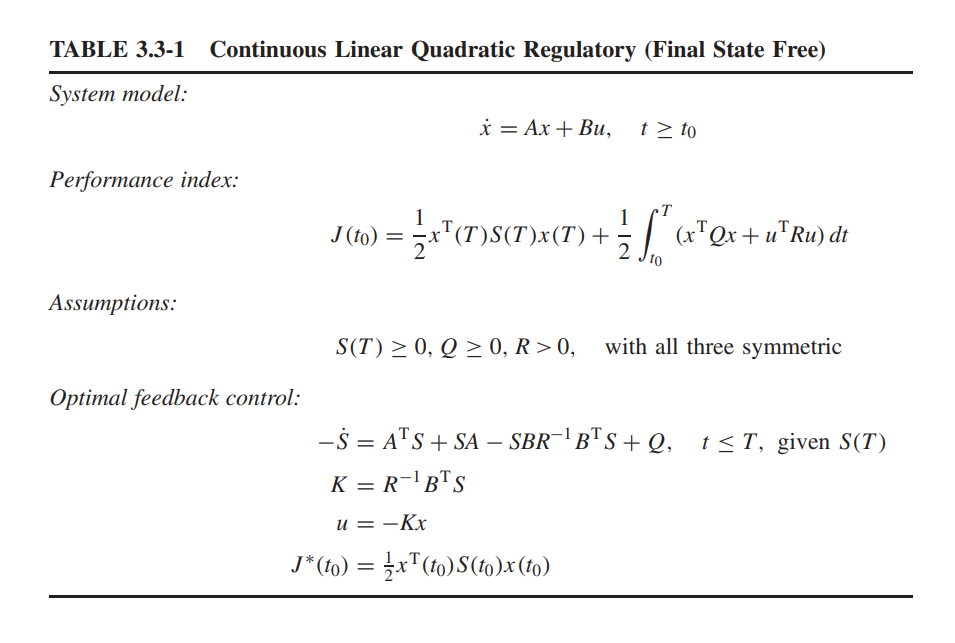

#### Invariant set 

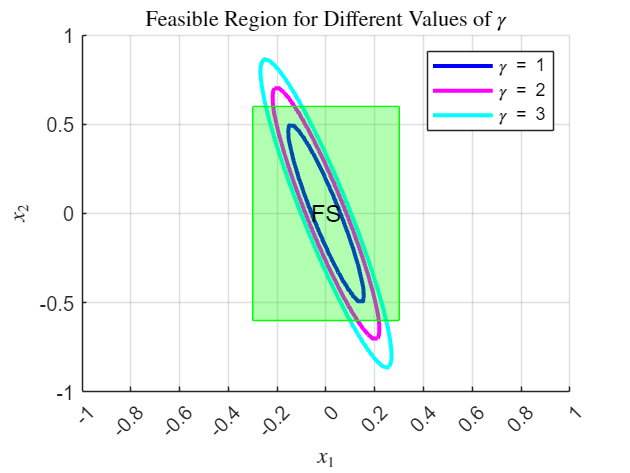

% Define the matrix P
P = [282.26, 81.23; 81.23, 27.38];

% Values for gamma
gamma_values = [1, 2, 3]; % Example values for gamma
colors = ['b', 'm', 'c']; % Colors for different gamma values

% Create a grid of points
x1 = linspace(-1, 1, 100);
x2 = linspace(-1, 1, 100);
[X1, X2] = meshgrid(x1, x2);

% Evaluate the quadratic form x^T P x for each point
QF = P(1,1)*X1.^2 + 2*P(1,2)*X1.*X2 + P(2,2)*X2.^2;

% Create a figure
figure;
hold on;

% Initialize an array to store plot handles
handles = [];

% Plot the feasible region for each value of gamma
for i = 1:length(gamma_values)
    gamma = gamma_values(i);
    % Determine the region where gamma - x^T P x >= 0
    Region = (gamma - QF >= 0);
    
    % Contour plot for the region boundary without filling
    contour(X1, X2, Region, [0.5 0.5], 'LineColor', 'none');
    
    % Contour plot for the boundary with specific color
    [~, h] = contour(X1, X2, QF, [gamma gamma], 'LineColor', colors(i), 'LineWidth', 2);
    handles = [handles, h]; % Store the handle for the legend
end

% Plot the feasible set for states
theta_max = 0.3; % Example value for maximum angle (rad)
theta_dot_max = 0.6; % Example value for maximum angular velocity (rad/s)
% Define the rectangle for feasible set
feasible_x1 = [-theta_max, theta_max, theta_max, -theta_max, -theta_max];
feasible_x2 = [-theta_dot_max, -theta_dot_max, theta_dot_max, theta_dot_max, -theta_dot_max];
% Fill the feasible set with green color and some transparency
fill(feasible_x1, feasible_x2, 'g', 'FaceAlpha', 0.3, 'EdgeColor', 'g');

% Add text "FS" to the center of the green area
text(0, 0, 'FS', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'FontSize', 12, 'Color', 'k');

% Labels and title
title('Feasible Region for Different Values of $\gamma$', 'Interpreter', 'latex');
xlabel('$x_1$', 'Interpreter', 'latex');
ylabel('$x_2$', 'Interpreter', 'latex');

% Add more ticks to the x-axis
xticks(-1:0.2:1);

% Add a legend with only the desired entries
legend(handles, {'\gamma = 1', '\gamma = 2', '\gamma = 3'}, 'Location', 'northeast');

% Grid settings
grid on;
hold off;


% Add a legend with only the desired entries
legend(handles, {'\gamma = 1', '\gamma = 2', '\gamma = 3'}, 'Location', 'northeast');

% Grid settings
grid on;
hold off; drawnow;

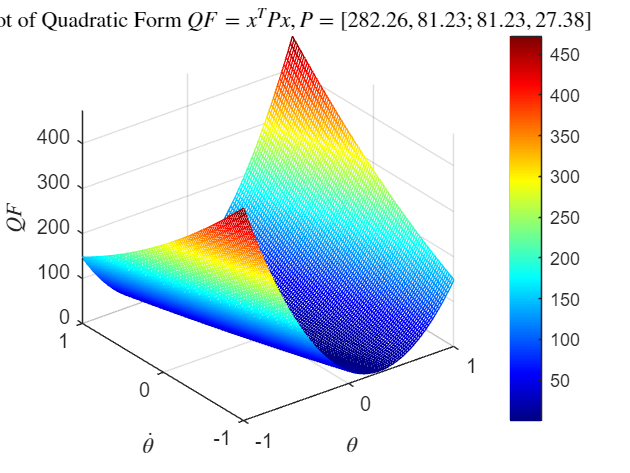

% Define the matrix P
P = [282.26, 81.23; 81.23, 27.38];

% Create a grid of points
theta = linspace(-1, 1, 100);
theta_dot = linspace(-1, 1, 100);
[Theta, Theta_dot] = meshgrid(theta, theta_dot);

% Evaluate the quadratic form QF for each point
QF = P(1,1)*Theta.^2 + 2*P(1,2)*Theta.*Theta_dot + P(2,2)*Theta_dot.^2;

% Create a 3D mesh plot
figure;
mesh(Theta, Theta_dot, QF);
colormap('jet'); % Change the color map from blue to red
colorbar;

% Labels and title
title('3D Plot of Quadratic Form $QF = x^T P x, P=[282.26, 81.23; 81.23, 27.38]$', 'Interpreter', 'latex');
xlabel('$\theta$', 'Interpreter', 'latex');
ylabel('$\dot{\theta}$', 'Interpreter', 'latex');
zlabel('$QF$', 'Interpreter', 'latex');

% Grid settings
grid on;
hold off; drawnow;

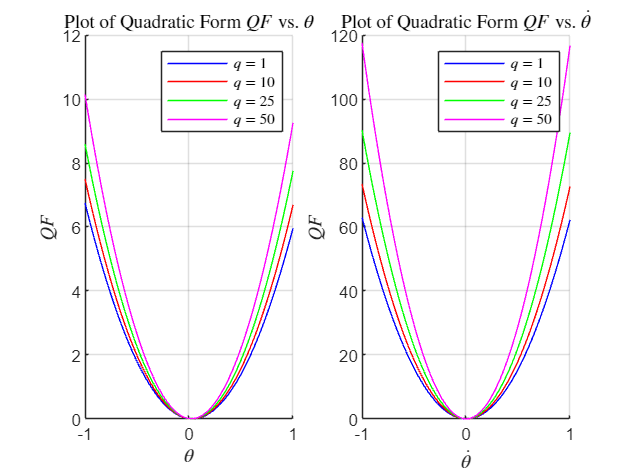

% System parameters
g = 9.81; % gravity (m/s^2)
l = 1.0;  % length of pendulum (m)
m = 1.0;  % mass of pendulum (kg)

% System dynamics
A = [0 1; g/l 0];
B = [0; 1/(m*l^2)];
[n, m] = size(B);

% Define different values of q
q_values = [1, 10, 25, 50];
colors = ['b', 'r', 'g', 'm']; % Colors for different q values
R = eye(m); % Define R

% Create a grid of points
theta = linspace(-1, 1, 100);
theta_dot = linspace(-1, 1, 100);
[Theta, Theta_dot] = meshgrid(theta, theta_dot);

% Create the figure
figure;

% First subplot: theta vs. QF
subplot(1, 2, 1);
hold on;
for i = 1:length(q_values)
    q = q_values(i);
    Q = q * eye(n);
    
    % LQR solution
    [K, Solution, Poles] = lqr(A, B, Q, R);
    
    % Define the matrix P
    P = Solution;
    
    % Evaluate the quadratic form QF for each point
    QF = P(1,1)*Theta.^2 + 2*P(1,2)*Theta.*Theta_dot + P(2,2)*Theta_dot.^2;
    
    % Plot theta vs. QF
    plot(theta, QF(:, 50), 'Color', colors(i), 'DisplayName', ['$q = ', num2str(q), '$']);
end
title('Plot of Quadratic Form $QF$ vs. $\theta$', 'Interpreter', 'latex');
xlabel('$\theta$', 'Interpreter', 'latex');
ylabel('$QF$', 'Interpreter', 'latex');
legend('show', 'Interpreter', 'latex');
grid on;
hold off;

% Second subplot: theta_dot vs. QF
subplot(1, 2, 2);
hold on;
for i = 1:length(q_values)
    q = q_values(i);
    Q = q * eye(n);
    
    % LQR solution
    [K, Solution, Poles] = lqr(A, B, Q, R);
    
    % Define the matrix P
    P = Solution;
    
    % Evaluate the quadratic form QF for each point
    QF = P(1,1)*Theta.^2 + 2*P(1,2)*Theta.*Theta_dot + P(2,2)*Theta_dot.^2;
    
    % Plot theta_dot vs. QF
    plot(theta_dot, QF(50, :), 'Color', colors(i), 'DisplayName', ['$q = ', num2str(q), '$']);
end
title('Plot of Quadratic Form $QF$ vs. $\dot{\theta}$', 'Interpreter', 'latex');
xlabel('$\dot{\theta}$', 'Interpreter', 'latex');
ylabel('$QF$', 'Interpreter', 'latex');
legend('show', 'Interpreter', 'latex');
grid on;
hold off; drawnow;

% System parameters
g = 10; % gravity (m/s^2)
l = 1.0;  % length of pendulum (m)
m = 2.0;  % mass of pendulum (kg)

% System dynamics
A = [0 1; g/l 0];
B = [0; 1/(m*l^2)];

% LQR solution
[n, m] = size(B);
q = 25; % Example value for Q
Q = q * eye(n);
R = eye(m);

[Solution,K,poles] = icare(A,B,Q,R,[],[],[]);


#### Nonlinear Programming 

import casadi.*

% Define the optimization variable
x = SX.sym('x', 2, 1); % Assuming x is a 2-dimensional vector

% Define the given matrices and constants
Q = 25 * eye(2); % State cost
R = 1; % Input cost
K = [40.62, 13.69];
P = [282.26, 81.23; 81.23, 27.38];

% Define gamma as a variable
gamma = SX.sym('gamma');

% Define the constraint function
constraint = gamma - x' * P * x;

% Define the functions f(x) and g(x) based on your problem
g = 10; % gravitational constant in m/s^2
l = 1.0; % length in meters
m = 2.0; % mass in kg

f_x = [x(2); g/l * sin(x(1))];
g_x = [0; 1/(m*l^2)];

% Ensure all terms are SX type
f_x = SX(f_x);
g_x = SX(g_x);

% Define the input constraints
u = -K * x;
input_constraint = u - 3; % Maximum torque constraint

% Define state constraints
state_constraints = [abs(x(1)) - 0.3; abs(x(2)) - 0.6];

% Define the function to be maximized
objective = -2 * x' * P * (f_x - g_x * K * x);

% Set up the NLP problem with state and input constraints
nlp = struct('x', [x; gamma], 'f', objective, 'g', [constraint; input_constraint; state_constraints]);

% Create the solver
opts = struct('ipopt', struct('print_level', 0, 'tol', 1e-6));
solver = nlpsol('solver', 'ipopt', nlp, opts);

% Define initial guess and bounds
x0 = [0; 0; 0.5]; % Initial guess for x and gamma  Very sensetive
lbg = [-inf; -inf; -inf; 0]; % Lower bound on constraints
ubg = [inf; 0; 0; 0]; % Upper bound on constraints

% Solve the problem
sol = solver('x0', x0, 'lbg', lbg, 'ubg', ubg);

      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)        0 (       0)         9
       nlp_g  |        0 (       0)        0 (       0)         9
  nlp_grad_f  |        0 (       0)        0 (       0)         9
  nlp_hess_l  |        0 (       0)        0 (       0)         7
   nlp_jac_g  |        0 (       0)        0 (       0)         9
       total  |   8.00ms (  8.00ms)   8.00ms (  8.00ms)         1



% Extract the solution
x_opt = full(sol.x);
gamma_opt = x_opt(end);

% Display the results
disp(gamma_opt)

    1.3154



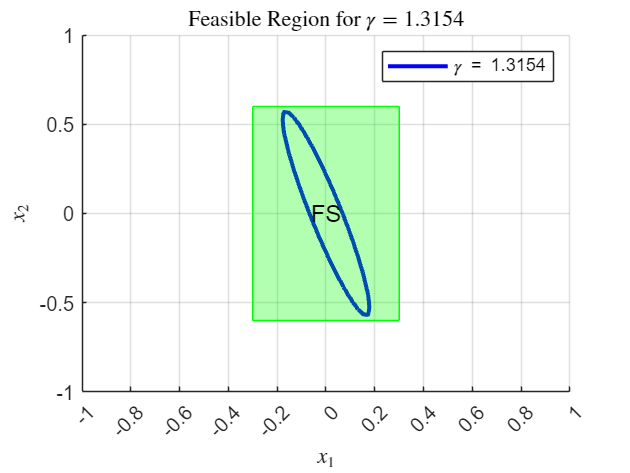

% Define the matrix P
P = [282.26, 81.23; 81.23, 27.38];

% Value for gamma
gamma = 1.3154; % Specific value for gamma
color = 'b'; % Color for the plot

% Create a grid of points
x1 = linspace(-1, 1, 100);
x2 = linspace(-1, 1, 100);
[X1, X2] = meshgrid(x1, x2);

% Evaluate the quadratic form x^T P x for each point
QF = P(1,1)*X1.^2 + 2*P(1,2)*X1.*X2 + P(2,2)*X2.^2;

% Create a figure
figure;
hold on;

% Plot the feasible region for gamma
% Determine the region where gamma - x^T P x >= 0
Region = (gamma - QF >= 0);

% Contour plot for the region boundary without filling
contour(X1, X2, Region, [0.5 0.5], 'LineColor', 'none');

% Contour plot for the boundary with specific color
[~, h] = contour(X1, X2, QF, [gamma gamma], 'LineColor', color, 'LineWidth', 2);

% Plot the feasible set for states
theta_max = 0.3; % Maximum angle (rad)
theta_dot_max = 0.6; % Maximum angular velocity (rad/s)
% Define the rectangle for feasible set
feasible_x1 = [-theta_max, theta_max, theta_max, -theta_max, -theta_max];
feasible_x2 = [-theta_dot_max, -theta_dot_max, theta_dot_max, theta_dot_max, -theta_dot_max];
% Fill the feasible set with green color and some transparency
fill(feasible_x1, feasible_x2, 'g', 'FaceAlpha', 0.3, 'EdgeColor', 'g');

% Add text "FS" to the center of the green area
text(0, 0, 'FS', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'FontSize', 12, 'Color', 'k');

% Labels and title
title('Feasible Region for $\gamma = 1.3154$', 'Interpreter', 'latex');
xlabel('$x_1$', 'Interpreter', 'latex');
ylabel('$x_2$', 'Interpreter', 'latex');

% Add more ticks to the x-axis
xticks(-1:0.2:1);

% Add a legend with only the desired entry
legend(h, {'\gamma = 1.3154'}, 'Location', 'northeast');

% Grid settings
grid on;
hold off; drawnow;

#### Closed-Loop 

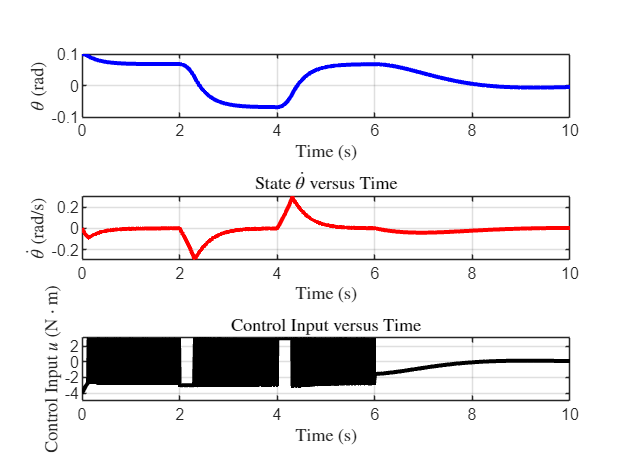

% System parameters
m = 2.0; % mass (kg)
l = 1.0; % length (m)
g = 10; % gravitational constant (m/s^2)
K = [40.62, 13.69]; % Feedback gain matrix
P = [282.26, 81.23; 81.23, 27.38]; % Positive-definite matrix
gamma = 1.3154; % Given gamma value

% Desired control input function
u_des = @(t, x) (t < 2) * 3 + (t >= 2 & t < 4) * (-3) + (t >= 4 & t < 6) * 3 + ...
    (t >= 6) * (m * l^2 * (-g/l * sin(x(1)) - [1.5, 1.5] * x));

% Initial state
x0 = [0.1; 0.0]; % Initial state [theta, theta_dot]

% Simulation time
tspan = [0 10]; % Time span for simulation

% Controller function
controller = @(t, x) (norm(u_des(t, x)) > 3 || (x' * P * x >= gamma)) * (-K * x) + ...
                      ~(norm(u_des(t, x)) > 3 || (x' * P * x >= gamma)) * u_des(t, x);

% System dynamics function
dynamics = @(t, x) [x(2); (g/l) * sin(x(1)) + controller(t, x) / (m * l^2)];

% Solve the system using ODE solver
[t, x] = ode45(dynamics, tspan, x0);

% Control input over time
u = arrayfun(@(i) controller(t(i), x(i,:)'), 1:length(t), 'UniformOutput', false);
u = cell2mat(u');

% Plot the state and control input versus time
figure;

% First subplot
subplot(3, 1, 1);
plot(t, x(:, 1), 'b', 'LineWidth', 2);
xlabel('Time (s)', 'Interpreter', 'latex');
ylabel('$\theta$ (rad)', 'Interpreter', 'latex');
grid on;

% Second subplot
subplot(3, 1, 2);
plot(t, x(:, 2), 'r', 'LineWidth', 2);
xlabel('Time (s)', 'Interpreter', 'latex');
ylabel('$\dot{\theta}$ (rad/s)', 'Interpreter', 'latex');
title('State $\dot{\theta}$ versus Time', 'Interpreter', 'latex');
grid on;

% Third subplot
subplot(3, 1, 3);
plot(t, u, 'k', 'LineWidth', 2);
xlabel('Time (s)', 'Interpreter', 'latex');
ylabel('Control Input $u$ (N$\cdot$m)', 'Interpreter', 'latex');
title('Control Input versus Time', 'Interpreter', 'latex');
grid on; 


drawnow;

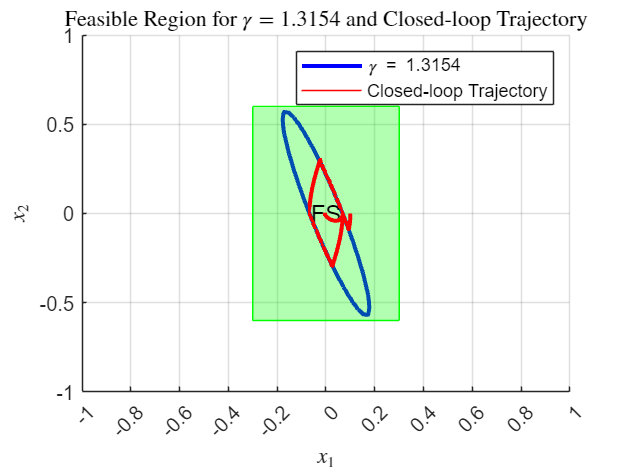


% Define the matrix P
P = [282.26, 81.23; 81.23, 27.38];

% Value for gamma
gamma = 1.3154; % Specific value for gamma
color = 'b'; % Color for the plot

% Create a grid of points
x1 = linspace(-1, 1, 100);
x2 = linspace(-1, 1, 100);
[X1, X2] = meshgrid(x1, x2);

% Evaluate the quadratic form x^T P x for each point
QF = P(1,1)*X1.^2 + 2*P(1,2)*X1.*X2 + P(2,2)*X2.^2;

% Create a figure
figure;
hold on;

% Plot the feasible region for gamma
% Determine the region where gamma - x^T P x >= 0
Region = (gamma - QF >= 0);

% Contour plot for the region boundary without filling
contour(X1, X2, Region, [0.5 0.5], 'LineColor', 'none');

% Contour plot for the boundary with specific color
[~, h] = contour(X1, X2, QF, [gamma gamma], 'LineColor', color, 'LineWidth', 2);

% Plot the feasible set for states
theta_max = 0.3; % Maximum angle (rad)
theta_dot_max = 0.6; % Maximum angular velocity (rad/s)
% Define the rectangle for feasible set
feasible_x1 = [-theta_max, theta_max, theta_max, -theta_max, -theta_max];
feasible_x2 = [-theta_dot_max, -theta_dot_max, theta_dot_max, theta_dot_max, -theta_dot_max];
% Fill the feasible set with green color and some transparency
fill(feasible_x1, feasible_x2, 'g', 'FaceAlpha', 0.3, 'EdgeColor', 'g');

% Add text "FS" to the center of the green area
text(0, 0, 'FS', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'FontSize', 12, 'Color', 'k');

% Plot the trajectory of the closed-loop system
plot(x(:, 1), x(:, 2), 'r', 'LineWidth', 2);

% Labels and title
title('Feasible Region for $\gamma = 1.3154$ and Closed-loop Trajectory', 'Interpreter', 'latex');
xlabel('$x_1$', 'Interpreter', 'latex');
ylabel('$x_2$', 'Interpreter', 'latex');

% Add more ticks to the x-axis
xticks(-1:0.2:1);

% Add a legend with only the desired entry
legend([h, plot(NaN, NaN, 'r')], {'\gamma = 1.3154', 'Closed-loop Trajectory'}, 'Location', 'northeast');

% Grid settings
grid on;
hold off; drawnow;

## HJ REACHABILITY

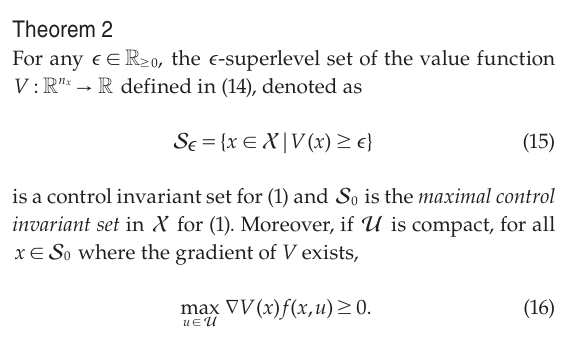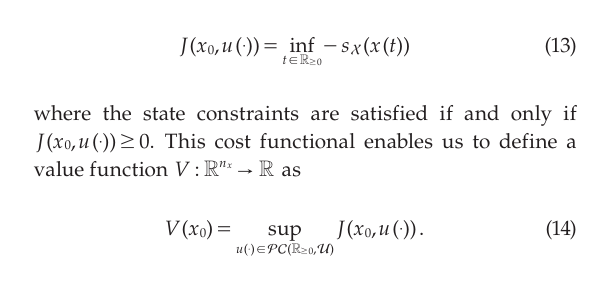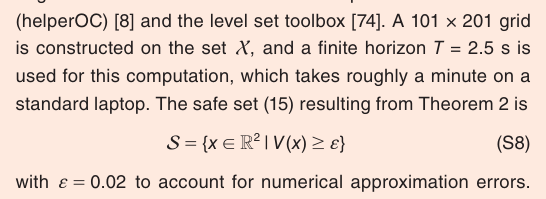

clear all
clc 
close all
% Add paths to ToolboxLS and helperOC
addpath(genpath('C:\Users\saber\OneDrive\Desktop\Research\Pablo-Marek-Begum\Weekly Meeting\29 July 2024\ToolboxLS'));
addpath(genpath('C:\Users\saber\OneDrive\Desktop\Research\Pablo-Marek-Begum\Weekly Meeting\29 July 2024\helperOC-master'));
theta_max=0.3;
theta_dot_max=0.6;
mins = [-theta_max; -theta_dot_max]; % Minimum values for each dimension
maxs = [theta_max; theta_dot_max]; % Maximum values for each dimension
nums = [101; 201]; % Number of grid points in each dimension

% Create the grid
g = createGrid(mins, maxs, nums);
data0 = shapeRectangleByCorners(g, [-theta_max, -theta_dot_max], [theta_max, theta_dot_max]);
HJIextraArgs.targetFunction = 0*data0;
t0 = 0;
tMax = 2.5;
dt = 0.01;
tau = t0:dt:tMax;
uMode = 'max';
schemeData.uMode = uMode;
% backward or forward?
schemeData.tMode = 'backward';
params.l=1;    % [m]        length of pendulum
params.m=2;    % [kg]       mass of pendulum
params.g=10; % [m/s^2]    acceleration of gravity
params.b=0; % [s*Nm/rad] friction coefficient
params.u_min=-3;
params.u_max=3;
x0=[0;0];
boat = InvertedPendulum(x0,params);
% Put grid and dynamic systems into schemeData
schemeData.grid = g;
schemeData.dynSys = boat;
schemeData.accuracy = 'high'; 
compMethod = 'none';
[data, tau2, ~] = ...
  HJIPDE_solve(data0, tau, schemeData, compMethod);

tau(i) = 0.010000
  Computing [0.000000 0.010000]...
  Computing [0.000950 0.010000]...
  Computing [0.001899 0.010000]...
  Computing [0.002849 0.010000]...
  Computing [0.003798 0.010000]...
  Computing [0.004748 0.010000]...
  Computing [0.005697 0.010000]...
  Computing [0.006647 0.010000]...
  Computing [0.007596 0.010000]...
  Computing [0.008546 0.010000]...
  Computing [0.009495 0.010000]...
tau(i) = 0.020000
  Computing [0.010000 0.020000]...
  Computing [0.010950 0.020000]...
  Computing [0.011899 0.020000]...
  Computing [0.012849 0.020000]...
  Computing [0.013798 0.020000]...
  Computing [0.014748 0.020000]...
  Computing [0.015697 0.020000]...
  Computing [0.016647 0.020000]...
  Computing [0.017596 0.020000]...
  Computing [0.018546 0.020000]...
  Computing [0.019495 0.020000]...
tau(i) = 0.030000
  Computing [0.020000 0.030000]...
  Computing [0.020950 0.030000]...
  Computing [0.021899 0.030000]...
  Computing [0.022849 0.030000]...
  Computing [0.023798 0.030000]...
 

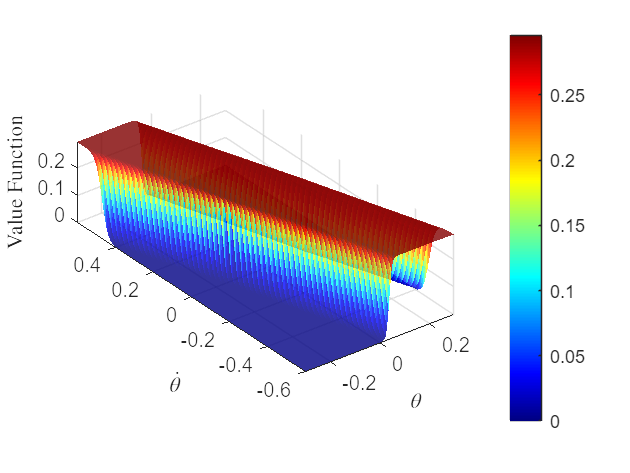



% Assuming g is your grid and data is your data array
data_dime = size(data);

% Create a figure for the animation
figure;

% Initialize the plot with the first time step
h = visFuncIm(g, data(:,:,1), 0.1);
hold on;
grid on;
axis equal;

% Set axis labels with LaTeX rendering
xlabel('$\theta$', 'Interpreter', 'latex');
ylabel('$\dot{\theta}$', 'Interpreter', 'latex');
zlabel('Value Function', 'Interpreter', 'latex');

% Loop through each time step to update the plot
for time_step = 1:data_dime(3)
    % Update the plot with the current time step data
    delete(h); % Remove the previous plot
    h = visFuncIm(g, data(:,:,time_step), 0.8); % Plot the new data
    
    % Update the figure window
    drawnow;
end

figure;
visFuncIm(g, data(:,:,end),1)

ans =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [101×201 double]
           YData: [101×201 double]
           ZData: [101×201 double]
           CData: [101×201 double]

  Show all properties


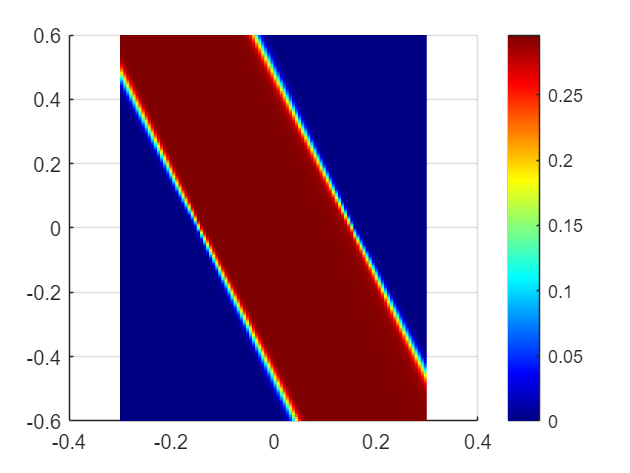

view(2)

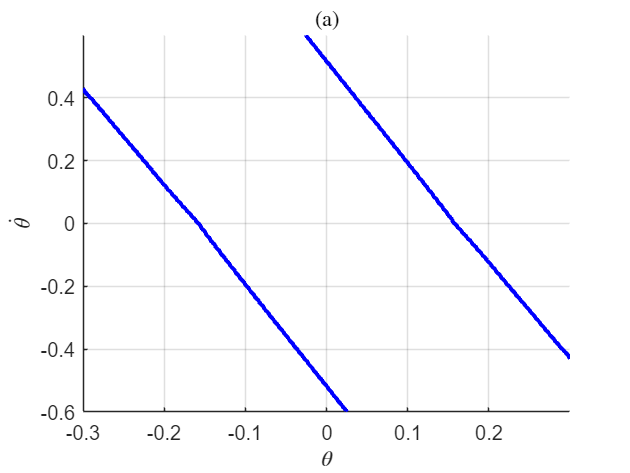

% Find and plot the level set at the boundary (typically 0)
level_set_value = 0.02; % Change this value if the boundary is at a different level

% Create a figure for the level set plot
figure;
hold on;
grid on;

% Extract and plot the level set contour at the boundary value
[C, h] = contour(g.xs{1}, g.xs{2}, data(:,:,end), [level_set_value level_set_value], 'LineColor', 'blue', 'LineWidth', 2);

% Customize the plot to match the desired style with LaTeX rendering
xlabel('$\theta$', 'Interpreter', 'latex');
ylabel('$\dot{\theta}$', 'Interpreter', 'latex');
title('(a)', 'Interpreter', 'latex');
grid on;
% axis([-theta_max theta_max -theta_dot_max theta_dot_max]);
hold on; drawnow;

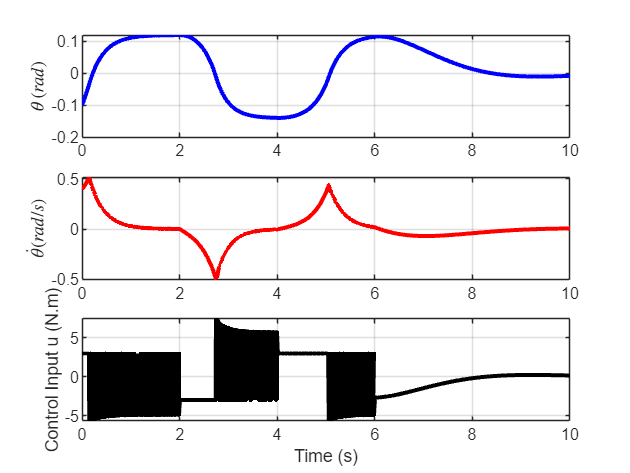

% System parameters
m = 2.0; % mass (kg)
l = 1.0; % length (m)
g = 10; % gravitational constant (m/s^2)
K = [40.62, 13.69]; % Feedback gain matrix

% Desired control input function
u_des = @(t, x) (t < 2) * 3 + (t >= 2 & t < 4) * (-3) + (t >= 4 & t < 6) * 3 + ...
    (t >= 6) * (m * l^2 * (-g/l * sin(x(1)) - [1.5, 1.5] * x));

% Initial state
x0 = [-0.1; 0.4]; % Initial state [theta, theta_dot]

% Simulation time
tspan = [0 10]; % Time span for simulation

% Define parallelogram constraints: A * x <= b
% These values are approximations based on the red boundary in the image
A = [-1.14, -0.3; 1, 0.3; 0, 1; 0, -1];
b = [0.16; 0.12; 0.6; 0.6];

% Check if x is inside the parallelogram
is_in_parallelogram = @(x) all(A * x <= b);

% Controller function
controller = @(t, x) (~is_in_parallelogram(x) || norm(u_des(t, x)) > 3) * (-K * x) + ...
                    is_in_parallelogram(x) * u_des(t, x);

% System dynamics function
dynamics = @(t, x) [x(2); (g/l) * sin(x(1)) + controller(t, x) / (m * l^2)];

% Solve the system using ODE solver
[t, x] = ode45(dynamics, tspan, x0);

% Control input over time
u = arrayfun(@(i) controller(t(i), x(i,:)'), 1:length(t), 'UniformOutput', false);
u = cell2mat(u');

% Plot the state and control input versus time
figure;
subplot(3, 1, 1);
plot(t, x(:, 1), 'b', 'LineWidth', 2);
xlabel('');
ylabel('$$\theta \, (rad)$$', 'Interpreter', 'latex');
grid on;

subplot(3, 1, 2);
plot(t, x(:, 2), 'r', 'LineWidth', 2);
xlabel('');
ylabel('$$\dot{\theta} (rad/s)$$', 'Interpreter', 'latex');

grid on;

subplot(3, 1, 3);
plot(t, u, 'k', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Control Input u (N.m)');
grid on; drawnow;

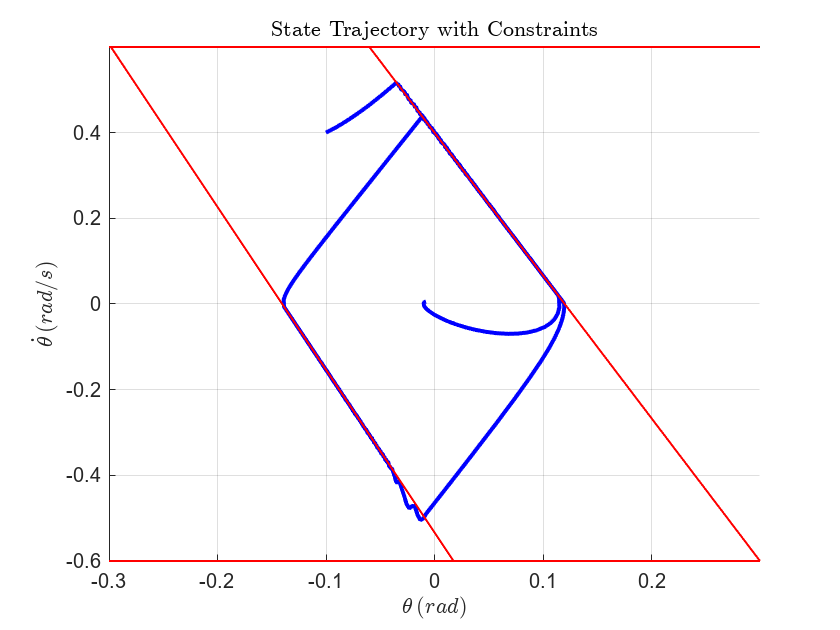

% Define inequality constraints: A * x <= b
% These values are approximations based on the red boundary in the image
A = [-1.14, -0.3; 1, 0.3; 0, 1; 0, -1];
b = [0.16; 0.12; 0.6; 0.6];

% Calculate constraints for each point
constraints = zeros(length(x(:,1)'), length(b));
for i = 1:length(b)
    constraints(:,i) = A(i,1) * x(:,1)' + A(i,2) * x(:,2)' - b(i);
end

% Find the points that satisfy all inequalities
% satisfies_constraints = all(constraints <= 0, 2);

% Plot the points and highlight the constrained region
figure;
hold on;
% For demonstration, I'll create a dummy state trajectory
plot(x(:, 1), x(:, 2), 'b', 'LineWidth', 2);

% Plot the boundary lines for each constraint
fimplicit(@(x, y) A(1,1) * x + A(1,2) * y - b(1), 'r', 'LineWidth', 1);
fimplicit(@(x, y) A(2,1) * x + A(2,2) * y - b(2), 'r', 'LineWidth', 1);
fimplicit(@(x, y) A(3,1) * x + A(3,2) * y - b(3), 'r', 'LineWidth', 1);
fimplicit(@(x, y) A(4,1) * x + A(4,2) * y - b(4), 'r', 'LineWidth', 1);
xlim([-0.3,0.3]);
ylim([-0.6,0.6]);
% Label axes and add a title
xlabel('X');
ylabel('Y');
title('Visualization of Inequality Constraints');
% Plot the state trajectory (assuming x is a predefined matrix)

% Label and style the plot
xlabel('$$\theta \, (rad)$$', 'Interpreter', 'latex');
ylabel('$$\dot{\theta} \, (rad/s)$$', 'Interpreter', 'latex');
title('State Trajectory with Constraints', 'Interpreter', 'latex');
grid on;

% Force MATLAB to render the figure immediately
drawnow;

## Control Barrier Function

clear all
clc
close all

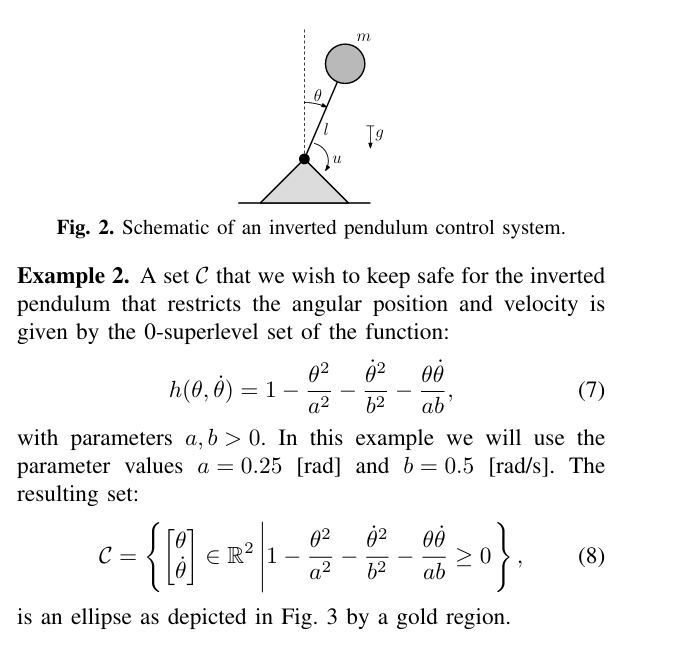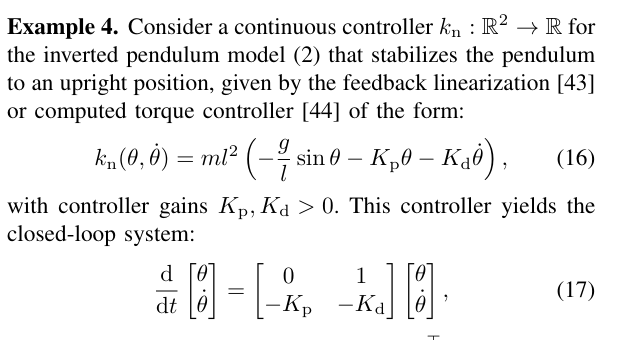

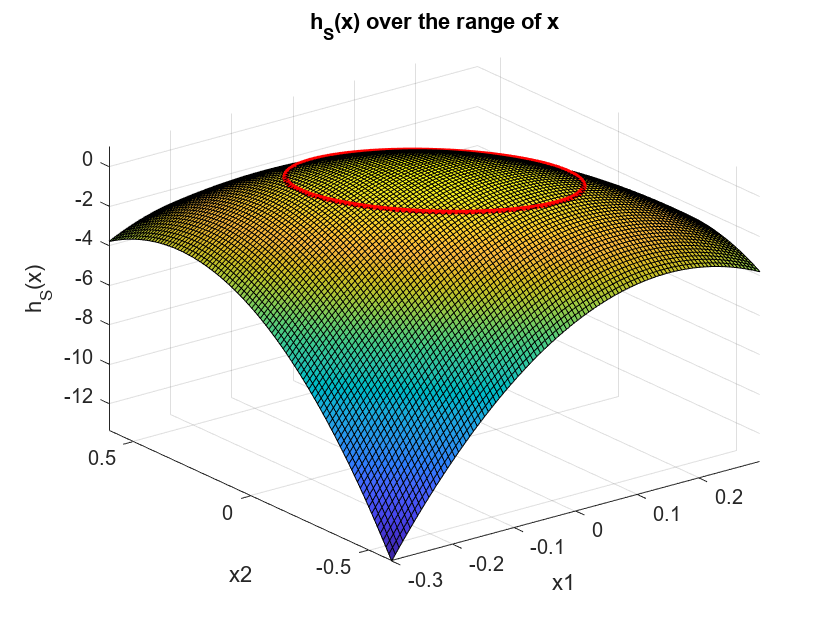

clear all
clc
close all

% Define the range for x
x1_min = -0.3;
x1_max = 0.3;
x2_min = -0.6;
x2_max = 0.6;

% Example parameters
a = 0.137;  % Example scalar value for a
b = 0.274;  % Example scalar value for b

% Create a grid of x values within the specified range
[x1, x2] = meshgrid(linspace(x1_min, x1_max, 100), linspace(x2_min, x2_max, 100));

% Initialize matrix to store h values
h_values = zeros(size(x1));

% Calculate h for each point in the grid
for i = 1:numel(x1)
    x = [x1(i); x2(i)];
    h_values(i) = hS_function(x, a, b);
end

% Plot the results
figure;
surf(x1, x2, h_values);
xlabel('x1');
ylabel('x2');
zlabel('h_S(x)');
title('h_S(x) over the range of x');
hold on;

% Visualize the region where h_S(x) >= 0
contour3(x1, x2, h_values, [0 0], 'LineWidth', 3, 'LineColor', 'r');
hold off;

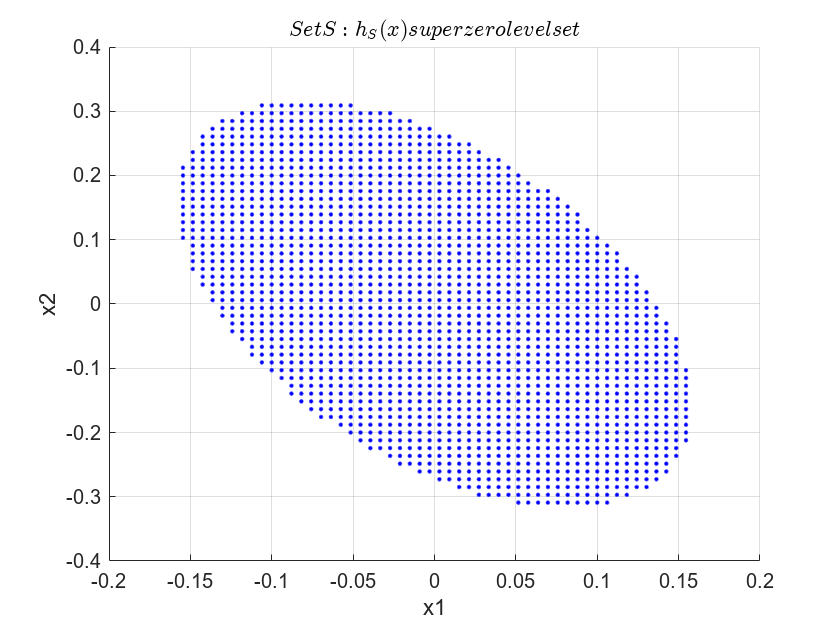


% Create a new figure for the set where h_S(x) >= 0
figure;
hold on;
xlabel('x1');
ylabel('x2');
title('$$Set S: h_S(x) super zero level set $$','Interpreter', 'latex');

% Plot the points where h_S(x) >= 0
for i = 1:numel(x1)
    if h_values(i) >= 0
        plot(x1(i), x2(i), 'b.');
    end
end

% Add grid and axis labels
grid on;
hold off;

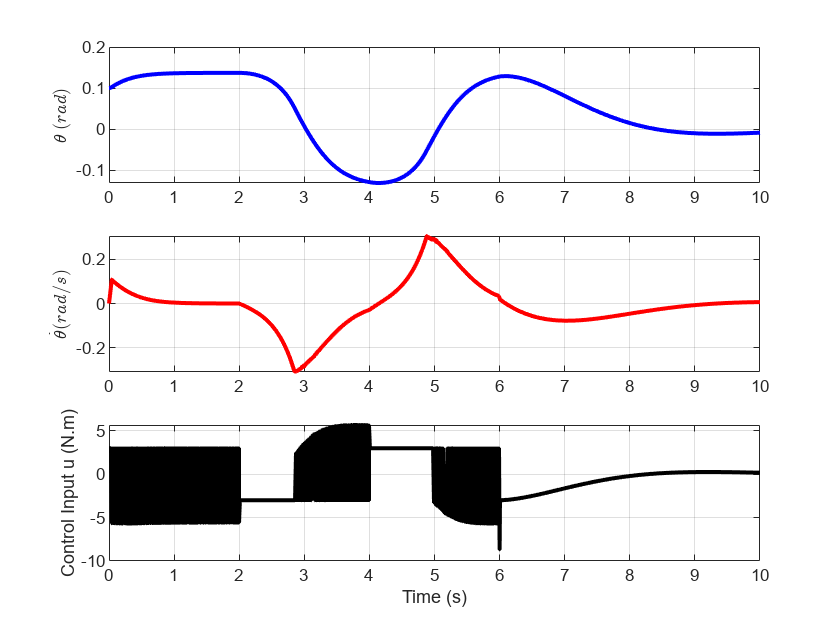


% System parameters
m = 2.0; % mass (kg)
l = 1.0; % length (m)
g = 10; % gravitational constant (m/s^2)
K = [40.62, 13.69]; % Feedback gain matrix

% Desired control input function
u_des = @(t, x) (t < 2) * 3 + (t >= 2 & t < 4) * (-3) + (t >= 4 & t < 6) * 3 + ...
    (t >= 6) * (m * l^2 * (-g/l * sin(x(1)) - [1.5, 1.5] * x));

% Initial state
x0 = [0.1; 0]; % Initial state [theta, theta_dot]

% Simulation time
tspan = [0 10]; % Time span for simulation



% Controller function
controller = @(t, x) (hS_function(x, a, b) <= 0 || norm(u_des(t, x)) > 3) * (-K * x) + ...
                    (hS_function(x, a, b) > 0) * u_des(t, x);

% System dynamics function
dynamics = @(t, x) [x(2); (g/l) * sin(x(1)) + controller(t, x) / (m * l^2)];

% Solve the system using ODE solver
[t, x] = ode45(dynamics, tspan, x0);

% Control input over time
u = arrayfun(@(i) controller(t(i), x(i,:)'), 1:length(t), 'UniformOutput', false);
u = cell2mat(u');

% Plot the state and control input versus time
figure;
subplot(3, 1, 1);
plot(t, x(:, 1), 'b', 'LineWidth', 2);
xlabel('');
ylabel('$$\theta \, (rad)$$', 'Interpreter', 'latex');
grid on;

subplot(3, 1, 2);
plot(t, x(:, 2), 'r', 'LineWidth', 2);
xlabel('');
ylabel('$$\dot{\theta} (rad/s)$$', 'Interpreter', 'latex');
grid on;

subplot(3, 1, 3);
plot(t, u, 'k', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Control Input u (N.m)');
grid on;

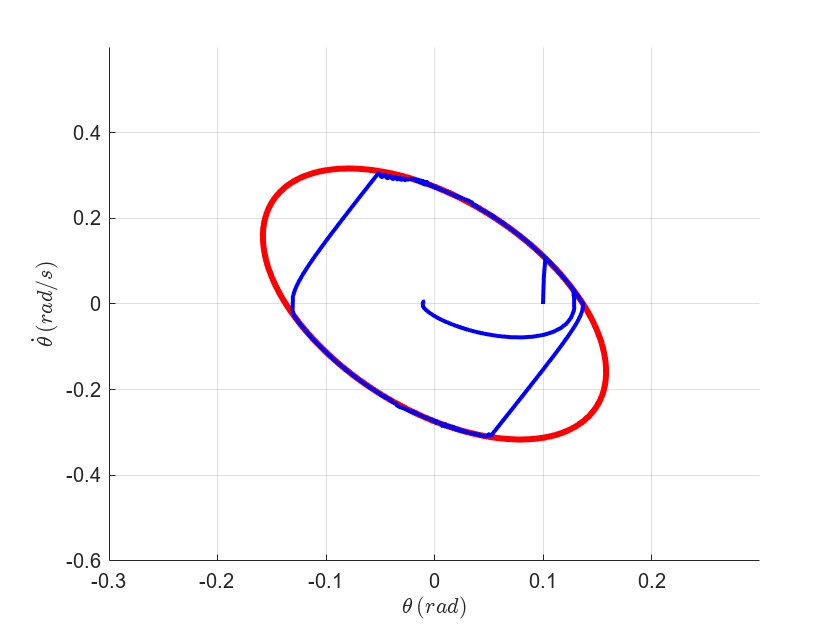



% Define inequality constraints: A * x <= b
% These values are approximations based on the red boundary in the image
A = [-1.14, -0.3; 1, 0.3; 0, 1; 0, -1];
b = [0.16; 0.12; 0.6; 0.6];

% Calculate constraints for each point
constraints = zeros(length(x(:,1)'), length(b));
for i = 1:length(b)
    constraints(:,i) = A(i,1) * x(:,1)' + A(i,2) * x(:,2)' - b(i);
end

% Find the points that satisfy all inequalities
% satisfies_constraints = all(constraints <= 0, 2);

% Plot the points and highlight the constrained region
figure;
hold on;


% Plot the zero level set of the h function
contour(x1, x2, h_values, [0 0], 'LineWidth', 3, 'LineColor', 'r');

% Plot the state trajectory
plot(x(:, 1), x(:, 2), 'b', 'LineWidth', 2);

% Set axis limits
xlim([-0.3, 0.3]);
ylim([-0.6, 0.6]);

% Label and style the plot
xlabel('$$\theta \, (rad)$$', 'Interpreter', 'latex');
ylabel('$$\dot{\theta} \, (rad/s)$$', 'Interpreter', 'latex');
grid on;
hold off;

drawnow;

# MPC controller for Inverted Pendulum

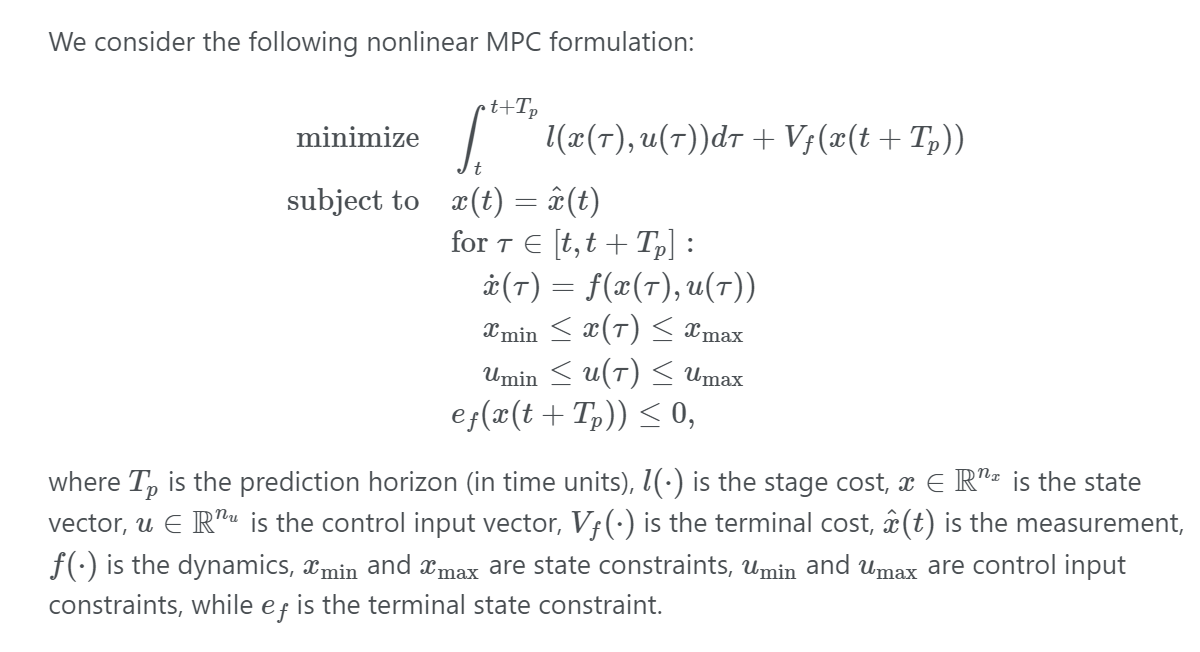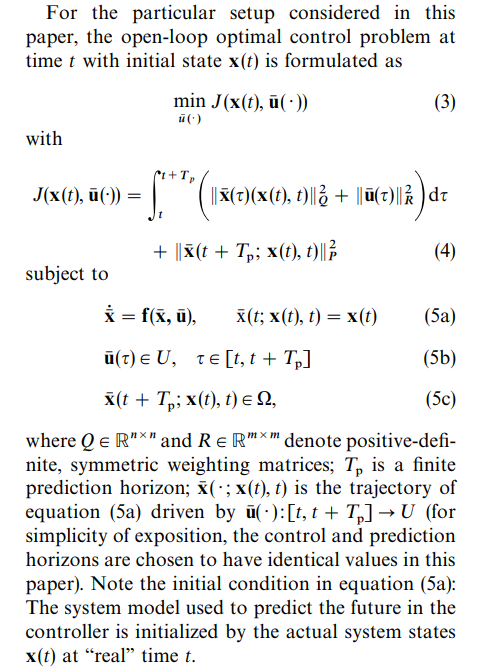

Adding Casadi path

clear all
clc 
close all
% Define the path to the folder containing CasADi
casadiPath = 'C:\Users\saber\OneDrive\Desktop\Research\Pablo-Marek-Begum\Weekly Meeting\15 July 2024\code\casadi-windows-matlabR2016a-v3.5.5';

% Add the CasADi folder to MATLAB's search path
addpath(casadiPath);

% Save the path for future MATLAB sessions (optional)
savepath;

Decision variables

dt = 0.1;
Tf = 120;
n_u = 1;
n_u_x = 2;
N_NMPC = 20;
states = zeros(n_u_x, Tf + 1); % Adding 1 to Tf for the final state
prediction = {};
states(:, 1) = [0; -0.45];
input = zeros(n_u, Tf);
J = zeros(1, Tf);
% P = [16.5926, 11.5926; 11.5926, 16.5926];
P=[282.26 81.23;81.23 27.38];
% alpha = 1.31;
alpha =1.31;

theta_max = 0.3; % Maximum angle (rad)
theta_dot_max = 0.6; % Maximum angular velocity (rad/s)

for iteration = 1:Tf
    [cost, input_seq, state_seq] = MPC(n_u, n_u_x, N_NMPC, states(:, iteration),alpha);
    input(iteration) = input_seq(1);
    J(iteration) = cost;
    prediction{iteration} = state_seq;
    states(:, iteration + 1) = F(@define_dynamics, states(:, iteration), input_seq(1), dt);
end

@1=(opti480_x_2[:2] = [0, -0.45]), mac(mac(@1[40:42]',
[[16.5926, 11.5926], 
 [11.5926, 16.5926]],zeros(1x2)),@1[40:42],0)
This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:      156
Number of nonzeros in inequality constraint Jacobian.:       60
Number of nonzeros in Lagrangian Hessian.............:      118

Total number of variables............................:       62
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:       40
Total number of inequality constraints...............:       61
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:       60
        inequality constraint


% Convert prediction to 3D array of size [2, 16, 120]
predictionArray = zeros(2, 16, Tf);
for iteration = 1:Tf
    % Ensure state_seq has 16 columns, adjust this if necessary
    state_seq = prediction{iteration};
    predictionArray(:, :, iteration) = state_seq(:, 1:16); % Adjust this if state_seq has more or fewer columns
end

% Define the quadratic form x'Px = 1
f = @(x, y) [x y] * P * [x; y] - alpha;

% Create a figure for terminal region and state trajectories
figure;

% Plot the terminal region
fimplicit(f, [-alpha alpha -alpha alpha],'Color','black'); % Adjust the range as necessary

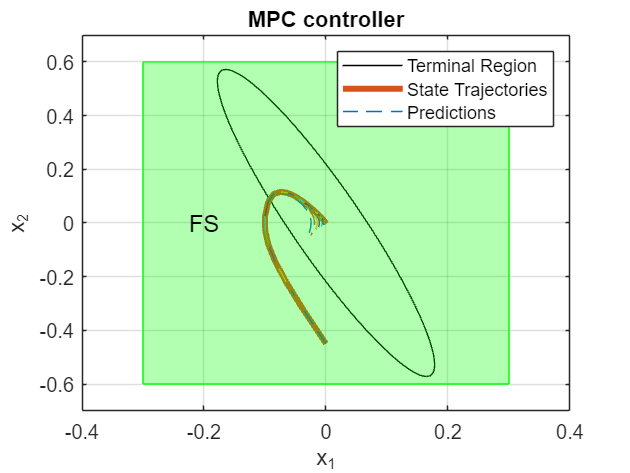

hold on

% Plot the state trajectories
plot(states(1,:), states(2,:), 'LineWidth', 3);

% Plot the predicted trajectories for each iteration
colors = lines(Tf); % Generate distinct colors for each iteration

for iteration = 1:Tf
    plot(prediction{iteration}(1,:), prediction{iteration}(2,:), '--', 'Color', colors(iteration, :));
end
% Plot the feasible set
x_feas = [-theta_max, theta_max, theta_max, -theta_max, -theta_max];
y_feas = [-theta_dot_max, -theta_dot_max, theta_dot_max, theta_dot_max, -theta_dot_max];
% Fill the feasible set with green color and some transparency
fill(x_feas, y_feas, 'g', 'FaceAlpha', 0.3, 'EdgeColor', 'g');

% Add text "FS" to the center of the green area
text(-0.2, 0.0, 'FS', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'FontSize', 12, 'Color', 'k');

% Add labels and title
xlabel('x_1');
ylabel('x_2');
title('MPC controller');
legend('Terminal Region', 'State Trajectories', 'Predictions');
grid on;
xlim([-0.4 0.4])
ylim([-0.7 0.7]); drawnow;

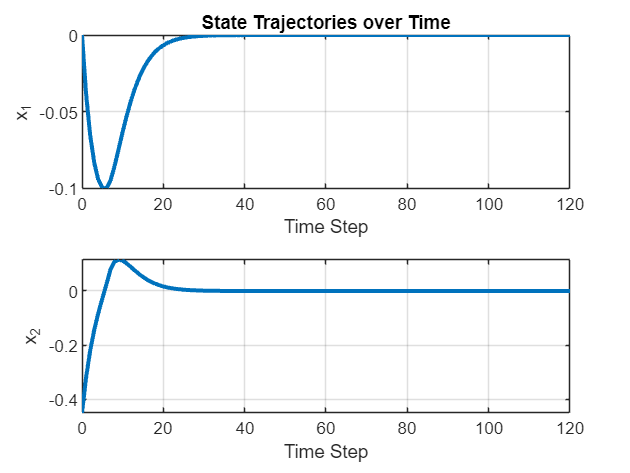


% Create a figure for state trajectories over time
figure;
subplot(2, 1, 1);
plot(0:Tf, states(1,:), 'LineWidth', 2);
xlabel('Time Step');
ylabel('x_1');
title('State Trajectories over Time');
grid on;

subplot(2, 1, 2);
plot(0:Tf, states(2,:), 'LineWidth', 2);
xlabel('Time Step');
ylabel('x_2');
grid on; drawnow;

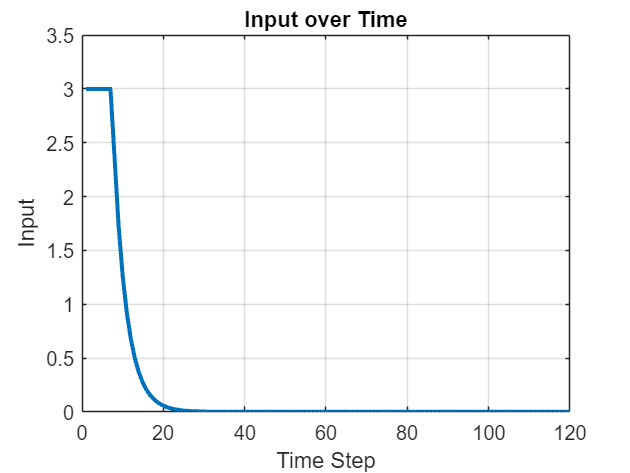


% Create a figure for input over time
figure;
plot(1:Tf, input, 'LineWidth', 2);
xlabel('Time Step');
ylabel('Input');
title('Input over Time');
grid on; drawnow;

# Nagumo's Theorem 

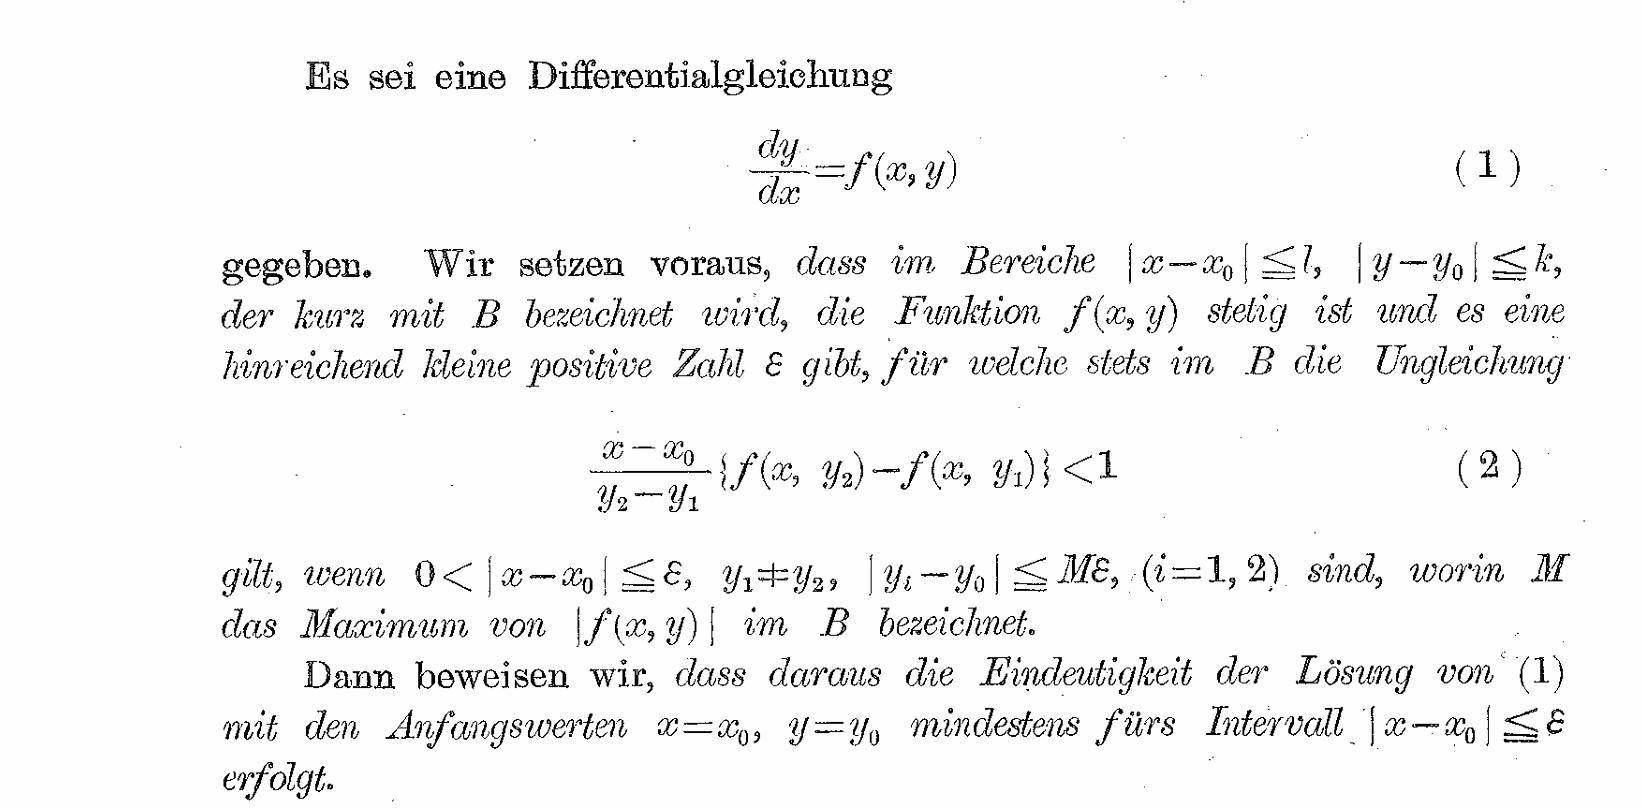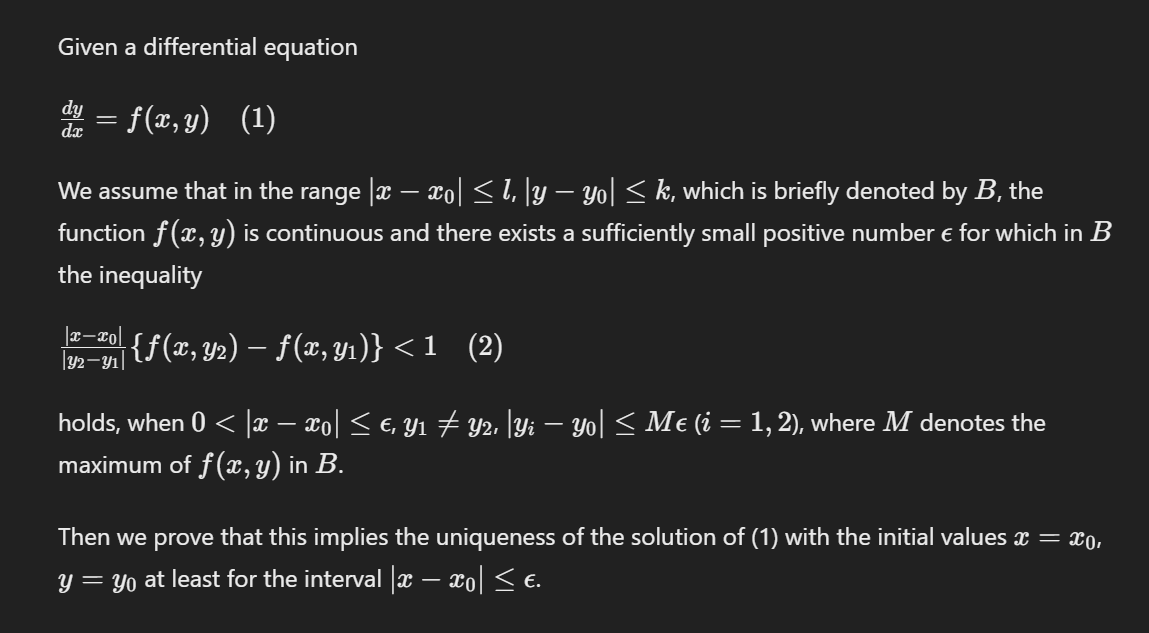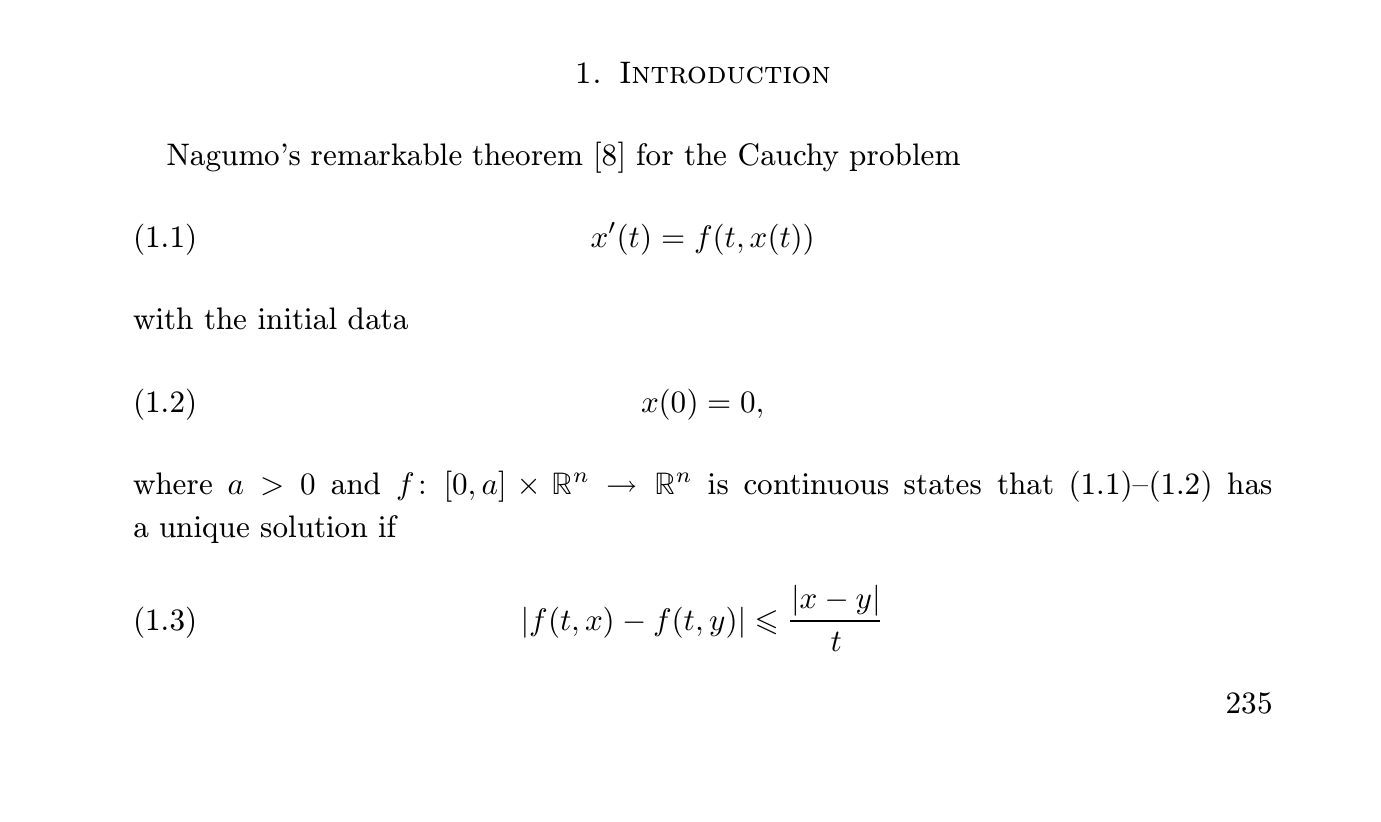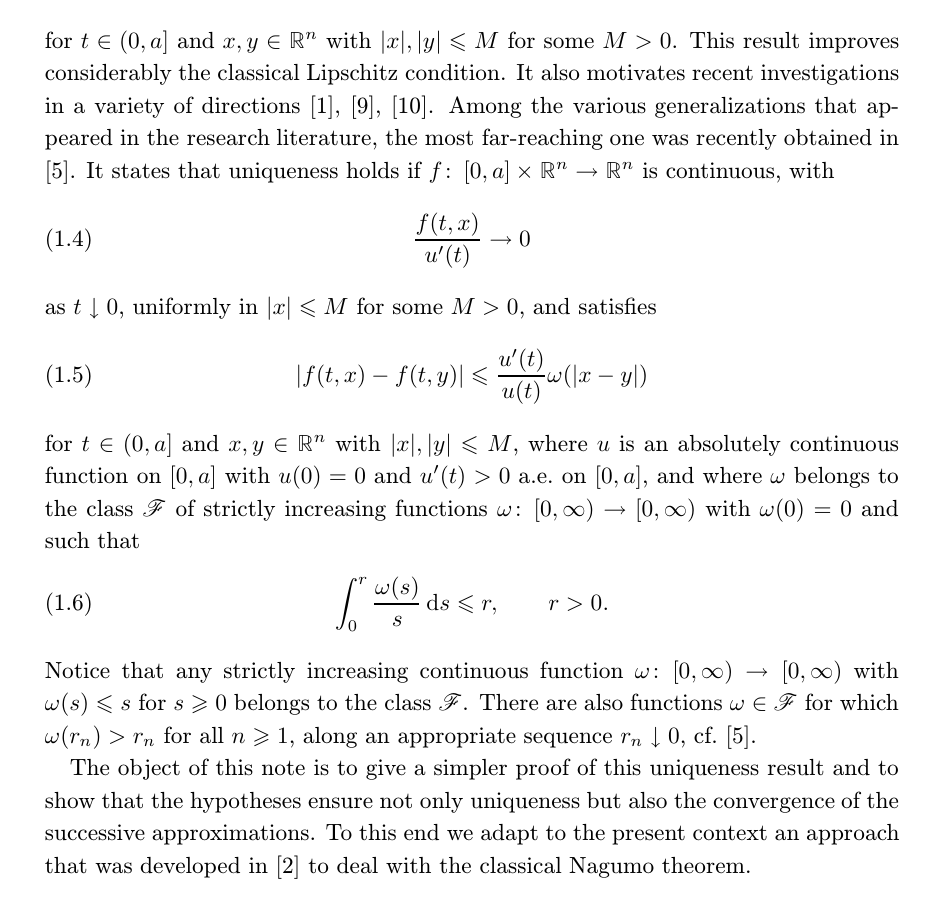

# Local Existence and Uniquencess 

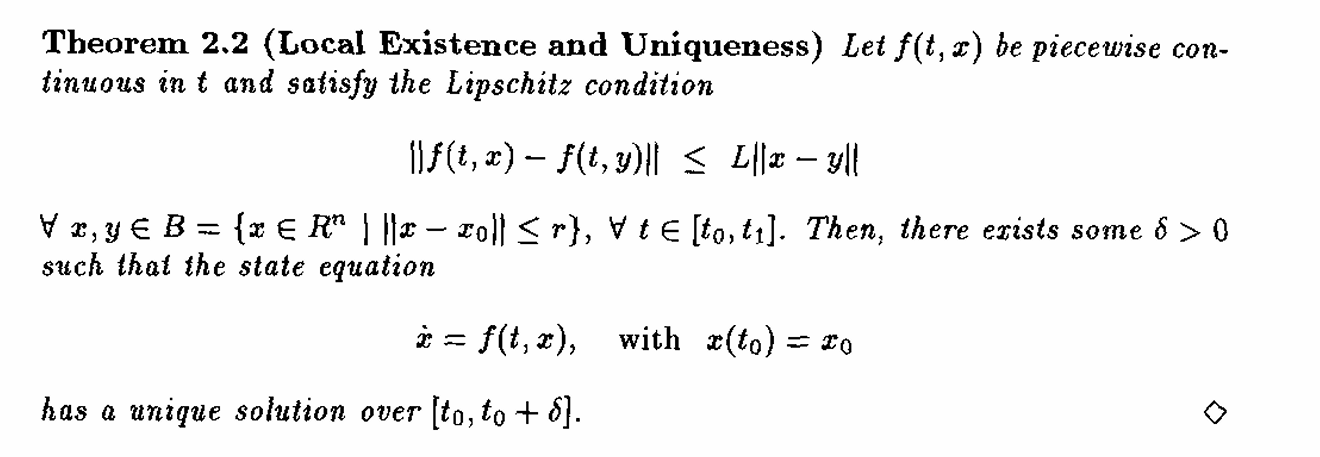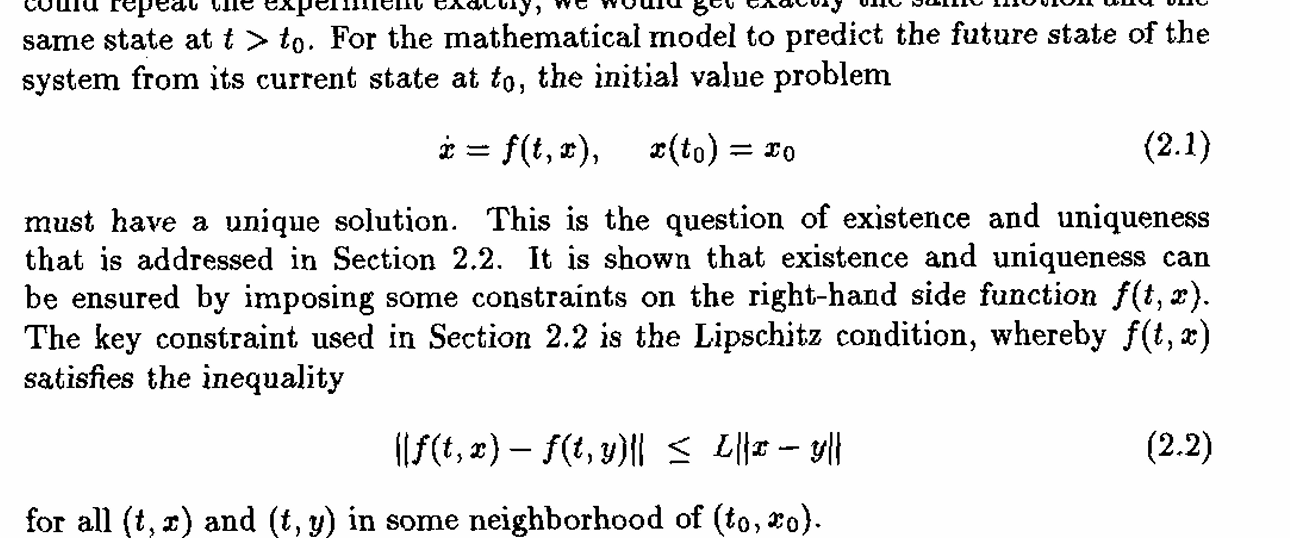

## Functions

function dxdt = pendulum_dynamics(t, x, g, l, m, control_input)
    theta = x(1);
    theta_dot = x(2);
    % Pendulum Dynamics Function
    % Calculate control input
    u = control_input(t, x);
    
    % System dynamics
    theta_ddot = (g/l) * sin(theta) + (1/(m*l^2)) * u;
    
    % Return the state derivatives
    dxdt = [theta_dot; theta_ddot];
end

function u = control_input(t, x, g, l, m)
    if t >= 0 && t < 2
        u = 3;
    elseif t >= 2 && t < 4
        u = -3;
    elseif t >= 4 && t < 6
        u = 3;
    else
        x1 = x(1);
        x2 = x(2);
        u = m * l^2 * ((-g/l)*sin(x1) - [1.5, 1.5] * [x1; x2]);
    end
end

function hS = hS_function(x, a, b)
% x should be a column vector
% a and b are scalars

% Construct the matrix
A = [1/a^2, 0.5/(a*b); 0.5/(a*b), 1/b^2];

% Calculate the value of the function
hS = 1 - x' * A * x;
end


Defined Dynamic 

function dxdt = define_dynamics(t, x, u)
    m = 2;
    l=1;
    g=9.81;
    coe1=g/l;
    coe2=1/m*l^2;
    dxdt = [x(2);
            coe1*sin(x(1))+coe2*u];
end

`RK4 integrator`

function x_plus = F(f,x,u,h)

% create RK4 integrator
k1 = f(0,x,u);
k2 = f(0,x+(h/2).*k1,u);
k3 = f(0,x+(h/2).*k2,u);
k4 = f(0,x+h.*k3,u);
x_plus = x + (h/6).*(k1+2*k2+2*k3+k4);

end

MPC controller 

function [cost,input,state] = MPC(n_u,n_u_x,N_NMPC,state,alpha)
import casadi.*
opti = casadi.Opti();

Td=0.1;
Q =eye(n_u_x);
R = eye(n_u);
% alpha=1.31;
P= [16.5926, 11.5926; 11.5926, 16.5926];

% initialize objective function
obj = 0;
u_min_v =-3;
u_max_v = 3;
x_min_v = [-0.3,-0.6]';
x_max_v = [0.3,0.6]';

% define control inputs as decision variables
u = opti.variable(n_u,N_NMPC);
% define states as decision variables
x = opti.variable(n_u_x,N_NMPC+1);
x(:,1)=state;
% initialize constraints;;
for k = 1:N_NMPC
    opti.subject_to(x(:,k+1) == F(@define_dynamics,x(:,k), u(:,k),Td));
end
% F(@define_dynamics, states(:,iteration), input_seq(1), dt)
for k = 1:N_NMPC
    
    % add stage cost to objective function
    obj = obj + x(:,k)'*Q*x(:,k) + u(:,k)'*R*u(:,k);
    
end

for k = 1:N_NMPC
    
    % control input constraints
    opti.subject_to(u_min_v <= u(:,k) <= u_max_v);
    % state constraints
    opti.subject_to(x_min_v <= x(:,k) <= x_max_v);
end

% add terminal cost to objective function
obj = obj + x(:,N_NMPC+1)'*P*x(:,N_NMPC+1);

display(x(:,N_NMPC+1)'*P*x(:,N_NMPC+1))
% terminal constraint
opti.subject_to(x(:,N_NMPC+1)'*P*x(:,N_NMPC+1) <= alpha);
% define optimization settings
opti.minimize(obj);
opti.solver('ipopt');
sol = opti.solve();

input=sol.value(u);
state=sol.value(x);
cost =sol.value(obj);

end

